transition_states = [0.5 0.5;0.8 0.2];
N = 10000000;

size = length(transition_states);
ts_tp = transpose(transition_states);  
A = ts_tp - eye(size);
ts = [A ; ones(1 , size)];
U = [zeros(size, 1) ;ones(1,1)] ;
P = linsolve(ts , U);
Hxx = zeros(1,size);
for i=1:size
    for j=1:size
        Hxx(1,i)=Hxx(1,i) - transition_states(i,j)*log2(transition_states(i,j));
    end
end
Hx = 0;
for i=1:size
    Hx = Hx + P(i)*Hxx(1,i);
end

K = 1:10;
G = zeros(1,length(K));
for k = 1 : length(K)
    G_k = entropy(transition_states,k);
    G(1,k)=G_k;
end

chain = zeros(1,N);
x = rand;
if x < P(1,1) % setting the source current state with state ptrobabilities
    chain(1,1) = 1;
else
    chain(1,1) = 2 ;
end
for i = 1 : N
    temp  = rand;
    switch chain(1,i)
        case 1
            if temp < transition_states(1,1)
                chain(1,i+1) = 1 ;
            else
                chain(1,i+1) = 2 ;
            end
        case 2
            if temp < transition_states(2,2) 
                chain(1,i+1) = 2 ;
            else
                chain(1,i+1) = 1 ;
            end 
    end
end

average_length_huffman = zeros(1,length(K));
HN = zeros(1, length(K));
for i = 1:length(K)
    average_length_huffman(1,i) = average_length(chain, i);
    HN(1,i) = average_length_huffman(1,i)/i;
end

H = zeros(1,length(K)); 
for i = 1:length(H)
    H(1,i) = Hx;
end
code_efficiency = zeros(1,length(K));
for i = 1:length(code_efficiency)
    code_efficiency(i) = H(1,i) / HN(1,i);
end
Hx

Hx = 0.8930

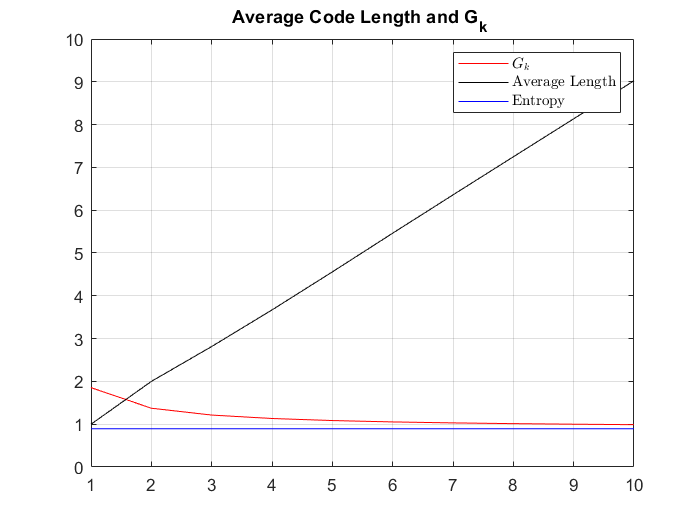

figure
plot(K,G,'r');
hold on ;
plot(K,average_length_huffman,'black');
hold on 
plot(K,H,'b');
title('Average Code Length and G_k ');
legend({'$G_k$','Average Length','Entropy'},'Interpreter','latex')
grid on;
hold off

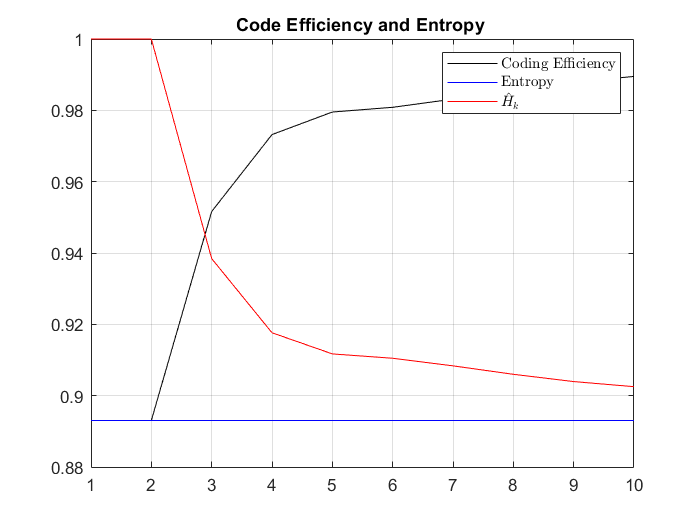

figure
plot(K,code_efficiency,'black');
hold on ;
plot(K,H,'b');
hold on ;
plot(K, HN,'r');
title('Code Efficiency and Entropy ');
legend({'Coding Efficiency','Entropy','$\hat{H}_k$'},'Interpreter','latex')
grid on;

function [average_length_huffman] = average_length(chain , k)
%step1: make super-symbol with k-bit groups
res = mod(length(chain),k);
len = length(chain) - res;
normalize_chain = zeros(1, len);
for i = 1:(len)
   normalize_chain(1,i) = chain(1,i);
end
group_num = length(normalize_chain)/k;
group_chain = reshape(normalize_chain, [k group_num]);
%step2: assigning symbols to k-bit sequences
symbol_chain = zeros(1, group_num);
for i = 1:group_num
    separate_chain = group_chain(:,i);
        symbol = 0;
    for j = 1:k
        symbol = symbol + separate_chain(j) * 2^(j);
    end
    symbol_chain(1,i) = symbol;
end
%step3: calculating symbol occurance probability
symbols = unique(symbol_chain);
symbol_count = histc(symbol_chain, symbols); 
symbol_probability = zeros(1, length(symbols));
for i = 1 : length(symbols)
    symbol_probability(1,i) = symbol_count(1, i) /length(symbol_chain);
end
%step4: using huffmandict to find average length
[~,average_length_huffman] = huffmandict(symbols,symbol_probability) ;
end

function[Gk] = entropy(transition_states,k)
size = length(transition_states);
%step 1 : find P 
ts_tp = transpose(transition_states);
% P = (phi)^T *P --> ((phi)^T - I) P = 0 --> Ax = 0    
A = ts_tp - eye(size);
% add sigma(pi)= 1
ts = [A ; ones(1 , size)];
U = [zeros(size, 1) ;ones(1,1)] ;
%solve Ax = 0
P = linsolve(ts , U);
% step 2 : find Hs1
Hs = 0;
for i = 1:size 
    Hs = Hs - P(i)* log2(P(i));
end
% step 2 : find Hs2s1
Hs2s1 = 0;
for i = 1:size 
    Hx = 0;
    for j = 1:size
        Hx = Hx - transition_states(i,j)*log2(transition_states(i,j));
    end
    Hs2s1 = Hs2s1 + P(i,1) * Hx;
end
% step 3 : calculating Gk
Gk = (Hs + k*Hs2s1) / k;
end